# Analysis of Round 1 EMG Data

Allyson Hur and Lily Jiang

Neurotech Fall 2023

All the data is currently stored in the `orange_crunch` directory. It's in a long form that needs to be preprocessed. We'll use the function `preprocessData.m` to high pass filter and chop up the data so it is of a format that we can work with.

addpath('analysis');

Now let's try preprocessing the data files. We want to combine them all into one dataset, so we'll first load and preprocess them separately.

load('orange_crunch/orange_crunch_1.mat');
[dataChTimeTr1, gesturelist1] = preprocessData(lsl_data, marker_data);

load('orange_crunch/orange_crunch_2.mat');
[dataChTimeTr2, gesturelist2] = preprocessData(lsl_data, marker_data);

load('orange_crunch/orange_crunch_3.mat');
[dataChTimeTr3, gesturelist3] = preprocessData(lsl_data, marker_data);

load('orange_crunch/orange_crunch_4.mat');
[dataChTimeTr4, gesturelist4] = preprocessData(lsl_data, marker_data);

load('orange_crunch/orange_crunch_5.mat');
[dataChTimeTr5, gesturelist5] = preprocessData(lsl_data, marker_data);

load('orange_crunch/orange_crunch_6.mat');
[dataChTimeTr6, gesturelist6] = preprocessData(lsl_data, marker_data);

load('orange_crunch/orange_crunch_7.mat');
[dataChTimeTr7, gesturelist7] = preprocessData(lsl_data, marker_data);

load('orange_crunch/orange_crunch_8.mat');
[dataChTimeTr8, gesturelist8] = preprocessData(lsl_data, marker_data);

load('orange_crunch/orange_crunch_9.mat');
[dataChTimeTr9, gesturelist9] = preprocessData(lsl_data, marker_data);

load('orange_crunch/orange_crunch_10.mat');
[dataChTimeTr10, gesturelist10] = preprocessData(lsl_data, marker_data);

% TODO: comment everything below out if you're trying to 
load('orange_crunch/orange_crunch_11.mat');
[dataChTimeTr11, gesturelist11] = preprocessData(lsl_data, marker_data);

load('orange_crunch/orange_crunch_12.mat');
[dataChTimeTr12, gesturelist12] = preprocessData(lsl_data, marker_data);

load('orange_crunch/orange_crunch_13.mat');
[dataChTimeTr13, gesturelist13] = preprocessData(lsl_data, marker_data);

load('orange_crunch/orange_crunch_14.mat');
[dataChTimeTr14, gesturelist14] = preprocessData(lsl_data, marker_data);

load('orange_crunch/orange_crunch_15.mat');
[dataChTimeTr15, gesturelist15] = preprocessData(lsl_data, marker_data);

load('orange_crunch/orange_crunch_16.mat');
[dataChTimeTr16, gesturelist16] = preprocessData(lsl_data, marker_data);

load('orange_crunch/orange_crunch_17.mat');
[dataChTimeTr17, gesturelist17] = preprocessData(lsl_data, marker_data);

load('orange_crunch/orange_crunch_18.mat');
[dataChTimeTr18, gesturelist18] = preprocessData(lsl_data, marker_data);

load('orange_crunch/orange_crunch_19.mat');
[dataChTimeTr19, gesturelist19] = preprocessData(lsl_data, marker_data);

load('orange_crunch/orange_crunch_20.mat');
[dataChTimeTr20, gesturelist20] = preprocessData(lsl_data, marker_data);

Now let's append all the data to each other and save to new variables.

dataChTimeTr = cat(3, dataChTimeTr1, ...
                      dataChTimeTr2, ...
                      dataChTimeTr3, ...
                      dataChTimeTr4, ...
                      dataChTimeTr5, ...
                      dataChTimeTr6, ...
                      dataChTimeTr7, ...
                      dataChTimeTr8, ...
                      dataChTimeTr9, ...
                      dataChTimeTr10, ...
                      dataChTimeTr11, ...
                      dataChTimeTr12, ...
                      dataChTimeTr13, ...
                      dataChTimeTr14, ...
                      dataChTimeTr15, ...
                      dataChTimeTr16, ...
                      dataChTimeTr17, ...
                      dataChTimeTr18, ...
                      dataChTimeTr19, ...
                      dataChTimeTr20);
gesturelist = vertcat(gesturelist1, ...
                      gesturelist2, ...
                      gesturelist3, ...
                      gesturelist4, ...
                      gesturelist5, ...
                      gesturelist6, ...
                      gesturelist7, ...
                      gesturelist8, ...
                      gesturelist9, ...
                      gesturelist10, ...
                      gesturelist11, ...
                      gesturelist12, ...
                      gesturelist13, ...
                      gesturelist14, ...
                      gesturelist15, ...
                      gesturelist16, ...
                      gesturelist17, ...
                      gesturelist18, ...
                      gesturelist19, ...
                      gesturelist20);

This should give us 2 new variables: `combinedDataChTimeTr` (the full surface EMG data to work with, across 4 channels) `and` `gesturelist` (the actual categories in order).

Now, extract the features and put them into a variable. We'll make a list of the names of features to include.

includedFeatures = {'var','rms','mav','wl','stdev','mean'};
Fs = 1;

Then extract those features. This code extracts the features for each channel separately unless you write an exception to this rule.

And lastly, save this to a file to reference later.

% TODO: uncomment this if using resubstitution
% feature_table = extractFeatures(dataChTimeTr, includedFeatures, Fs);
% labels = gesturelist;
% save("latest_feature_table.mat","feature_table","labels");

% TODO: uncomment this if using train/test split
numTraining = 480;  % defines the split ratio
matrixSize = size(dataChTimeTr);
numDatapoints = matrixSize(3);
clearvars matrixSize

feature_table = extractFeatures(dataChTimeTr(:, :, 1:numTraining), includedFeatures, Fs);
labels = gesturelist(1:numTraining, :);
save("feature_table_train.mat","feature_table","labels");

feature_table = extractFeatures(dataChTimeTr(:, :, (numTraining+1):numDatapoints), includedFeatures, Fs);
labels = gesturelist((numTraining+1):numDatapoints, :);
save("feature_table_test.mat","feature_table","labels");

Select a subset of features. I'm starting off by selecting my favorite 2 features based on the offline analysis assignment I completed last week: waveform length and standard deviation

selected_features = [13 14 15 16 17 18 19 20];
% TODO: change values in `selected_features` to include
% features you want
% The initial attempt was with WL + St Dev (13 14 15 16 17 18 19 20)
% Some of the high performing features are listed below:
% RMS: 5 6 7 8
% WL: 13 14 15 16
% St dev: 17 18 19 20

clearvars feature_table labels

## Load the feature data and put into X and y matrices

Look inside the function below to set things like train-test split.

% filesToLoad = {"latest_feature_table.mat"};
filesToLoad = {"feature_table_train.mat", "feature_table_test.mat"};
[X_train, y_train, X_test, y_test] = featuresTo_X_y_train_test(filesToLoad, selected_features);


## Build a classifier and do k-fold cross-validation

% Perform cross-validation
KFolds = 5;
cvp_kfold = cvpartition(y_train, 'KFold', KFolds);

% Make empty vector to store predictions from k-fold cross-validation
validation_predictions = NaN(length(y_train),1);

% Loop through all the folds
for fold = 1:KFolds
    % Within each partition, assign the data for that fold to the
    % cross-validation training data
    kfold_partial_data_X_train = X_train(cvp_kfold.training(fold), :);
    kfold_partial_data_y_train = y_train(cvp_kfold.training(fold), :);
    
    % Within each partition, assign the data for that fold to the
    % cross-validation validation (testing) data
    kfold_partial_data_X_val = X_train(cvp_kfold.test(fold), :);
    %kfold_partial_data_y_val = y_train(cvp_kfold.test(fold), :);

    % Build a temporary model for this subset of the data (k-1)/k
    kfold_classifier = createClassifier(kfold_partial_data_X_train,kfold_partial_data_y_train);

    % Make predictions with the kfold_classifier  (temporary classifier on
    % subset of data)
    kfold_predictions = kfold_classifier.predict(kfold_partial_data_X_val);

    % Store predictions in the original order
    validation_predictions(cvp_kfold.test(fold), :) = kfold_predictions;
end

% Calculate cross-validation metrics
[validation_accuracy ] = calculateMetrics(y_train, validation_predictions)

validation_accuracy = 0.6083

## Build a classifer on all of the training data

By making a createClassifier function, we can better ensure that the classifier we're using for the model and for cross-validation are the same. You can also make this into a function with other options (like which classifier to use or some parameter in the classifier that you want to vary).

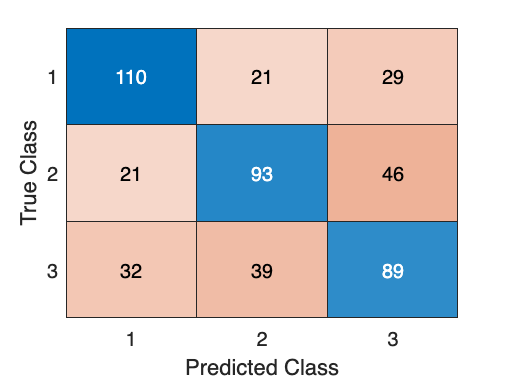

% Create a classifier
currentClassifier = createClassifier(X_train, y_train);

% Calculate the confusion matrix
CM = confusionmat(y_train, validation_predictions);
confusionchart(CM);


% Calculate average F1 across the 3 classes
F1 = calculateF1(CM)

F1 = 0.6082

## Use classifier to predict on training data (resubstitution)

y_train_predictions = currentClassifier.predict(X_train);
[train_accuracy] = calculateMetrics(y_train, y_train_predictions)

train_accuracy = 0.8688

## Use classifier to predict on test data

y_test_predictions = currentClassifier.predict(X_test);
[test_accuracy] = calculateMetrics(y_test, y_test_predictions)

test_accuracy = 0.4833

## Results

Using the initial script conditions (resubstitution, `fitcdiscr` classifier, and WL + St Dev for features), we got the following accuracies:

- Training accuracy: 0.5867

- Testing accuracy: 0.5733

## Improvement Attempts

We made 3 attempts to improve the algorithm.

1. Changing the split of data to use train/test split. The first 180 trials were chosen to be the train data, and the remaining 120 trials were chosen to be the test data.

- Instead of the line `filesToLoad = {"latest_feature_table.mat"};`, we tried `filesToLoad = {"feature_table_train.mat", "feature_table_test.mat"};`. This improved the training accuracy from 0.5867 to 0.6111, but dropped the testing accuracy from 0.5733 to 0.4917.

- **While this negatively impacted our testing accuracy, we decided to adopt this change anyways because we noticed it provided consistent train/test accuracies across all times running the program. With our original resubstition method, the accuracy values kept jumping around each time we re-ran (since there's an element of random selection). Resubstitution would've made everything more tedious because we'd have to run this file multiple times and take an average to determine whether our changes were actually working.**

2. Changing the classifier function to try `fitctree` and `knn` (this is done in the `createClassifier` function)

- `fitctree` greatly improved the training accuracy from 0.6111 to 0.8833, and the testing accuracy from 0.4917 to 0.5250

- `knn` improved the training accuracy from 0.6111 to 0.7667, but harmed the testing accuracy (0.4917 to 0.4750)

- **We decided to switch our classifier function from **`fitcdiscr`** to **`fitctree`

3. Adding a new feature in addition to the Waveform Length and Standard Deviation, and testing combinations of the three features

- RMS was another high performing feature from our previous feature analysis, so we added the 4 channels (5, 6, 7, and 8) into the `selected_features` variable

- We tried several combos of the 3 features and found the best performing one to be the original Waveform Length and Standard Deviation. All other combos (RMS+WL, RMS+StDev, RMS+WL+StDev) yielded lower test accuracies.

- **We did not change the features we were using**

## More data!

After our initial improvement attempts, we decided to add another 300 datapoints (for a total of 600 trials) to try to bolster the algorithm and prepare for a live classification. Initially, we started with the same ratio as before, so 360 training and 240 testing datapoints.

We uncommented the necessary lines of code, then re-ran this program to yield the following accuracies:

- Training accuracy: 0.8639

- Testing accuracy: 0.3917

This testing accuracy is rather low! Adding in extra data seemed to be harmful, but we tried several methods to improve this accuracy.

1. Changing the split ratio to be 480/120

- Training accuracy: 0.8688

- Test accuracy: 0.4833

# Helper functions

The code after this are functions that you can use and modify. By using functions to do more of the detailed work, we can better see the big picture above. And, we can better reuse the same code.

Feature extraction function

function [feature_table] = extractFeatures(dataChTimeTr,includedFeatures, Fs)
    
    % List of channels to include (can change to only use some)
    includedChannels = 1:size(dataChTimeTr,1);
    
    % Empty feature table
    feature_table = table();

    
    for f = 1:length(includedFeatures)
        N = size(dataChTimeTr, 2);

        switch includedFeatures{f}
            case 'var'
                fvalues = squeeze(var(dataChTimeTr,0,2))';
              
            case 'rms'
                fvalues = squeeze(sqrt((1/N) * sum(dataChTimeTr.^2, 2)))';

            case 'mav'
                fvalues = (1/N) * squeeze(sum(abs(dataChTimeTr.^2), 2))';

            case 'wl'
                fvalues = (1/N) * squeeze(sum(abs(diff(dataChTimeTr, 1, 2)), 2))';

            case 'stdev'
                fvalues = squeeze(std(dataChTimeTr,0,2))';

            case 'mean'
                fvalues = (1/N) * squeeze(sum(dataChTimeTr, 2))';

            otherwise
                % If you don't recognize the feature name in the cases
                % above
                disp(strcat('unknown feature: ', includedFeatures{f},', skipping....'))
                break % This breaks out of this round of the for loop, skipping the code below that's in the loop so you don't include this unknown feature
        end

        % If there is only one feature, just name it the feature name
        if size(fvalues,2) == 1
            feature_table = [feature_table table(fvalues,...
                'VariableNames',string(strcat(includedFeatures{f})))];
        
        % If the number of features matches the number of included
        % channels, then assume each column is a channel
        elseif size(fvalues,2) == length(includedChannels)
            %Put data into a table with the feature name and channel number
            for  ch = includedChannels
                feature_table = [feature_table table(fvalues(:,ch),...
                    'VariableNames',string(strcat(includedFeatures{f}, '_' ,'Ch',num2str(ch))))]; %#ok<AGROW>
            end
        
        
        else
        % Otherwise, loop through each one and give a number name 
            for  v = 1:size(fvalues,2)
                feature_table = [feature_table table(fvalues(:,v),...
                    'VariableNames',string(strcat(includedFeatures{f}, '_' ,'val',num2str(v))))]; %#ok<AGROW>
            end
        end

    end 

end

## Create X_train, y_train, X_test, and y_test. Configure train-test split here.

function [X_train, y_train, X_test, y_test] = featuresTo_X_y_train_test(filesToLoad, selected_features)


True if you have separate test data to load (or just use all the train data again), false if you want to partition it from the data.

    if size(filesToLoad,2) == 2
        isSeparateTestData = true;
    elseif size(filesToLoad,2) == 1
        isSeparateTestData = false;
    else 
        error("Wrong number of files to load.")
    end
    
    %

Load the training data. This is expecting your features to be in a table called feature_table. 

    load(filesToLoad{1})

#### If separate test data

    if isSeparateTestData   
        % Put the train data into X and y  
        X_train = feature_table(:,selected_features);
        y_train = labels;
    
    
        % If you just want to use your train data again (resubstitution), just
        % get rid of the load part and repeat the step above.
    
        % Load the test data (here, it's the same file.. so fix this)
        load(filesToLoad{2});
    
        % Put the test data into X and y  
        % You might need to change variable names here
        X_test = feature_table(:,selected_features);
        y_test = labels;
    

#### If split the train / test data from one file

    else
        % If you want to partition your data into train and test
        holdout_proportion_test = 0.25;
        try 
            % If it exists, Load a saved partition from last time (so you don't keep
            % shufflig which dat is your train and test)
            load("lastCVpartition.mat")
            disp("loading prior training-test partition")
            if cvtt.NumObservations ~= length(labels) || cvtt.TestSize/cvtt.NumObservations ~= holdout_proportion_test
                warning('Loaded cv partition does not match number of observations, delete or rename and rerun, making a temporary new one')
                
                cvtt = cvpartition(labels,"HoldOut",holdout_proportion_test); % Decimal is how much to hold out for test
            end
        catch
            cvtt = cvpartition(labels,"HoldOut",holdout_proportion_test); % Decimal is how much to hold out for test
            save("./lastCVpartition.mat","cvtt");
            disp('Making new training-test partiton')
        end
        
        % Train data
        X_train = feature_table(training(cvtt),selected_features);
        y_train = labels(training(cvtt));
    
        %Test datac
        X_test = feature_table(test(cvtt),selected_features);
        y_test = labels(test(cvtt));
    end
end


## Build a model based on data

There are various models that you can use here for 3 classes. You can add more details / parameters here.

function [theClassifier, CM] = createClassifier(dataIn, labelsIn)
    
    % TODO: comment out 1 classifier

    % Linear discriminant analysis
    % theClassifier = fitcdiscr(dataIn,labelsIn);

    % Decision tree
    theClassifier = fitctree(dataIn,labelsIn);

    % fitcknn does k-nearest neighbors
    % theClassifier = fitcknn(dataIn,labelsIn,...
    %    "NumNeighbors",3);
end



## Calculate key metrics

You can put your other key metrics (such as F1 score) in here. You'll need to add more outputs to your function. 

function [accuracy ] = calculateMetrics(true_labels, predicted_labels)
    
    accuracy = sum(true_labels == predicted_labels) / length(true_labels);
    
end


## Calculate average F1 score across the 3 classes

function [F1] = calculateF1(CM)
    TP1 = CM(1, 1);
    FN1 = CM(1, 2) + CM(1, 3);
    FP1 = CM(2, 1) + CM(3, 1);
    % TN1 = CM(2, 2) + CM(2, 3) + CM(3, 2) + CM(3, 3);
    TP2 = CM(2, 2);
    FN2 = CM(2, 1) + CM(2, 3);
    FP2 = CM(1, 2) + CM(3, 2);
    TP3 = CM(3, 3);
    FN3 = CM(1, 3) + CM(2, 3);
    FP3 = CM(3, 1) + CM(3, 2);
    
    precision1 = TP1 / (TP1 + FP1);
    recall1 = TP1 / (TP1 + FN1);
    precision2 = TP2 / (TP2 + FP2);
    recall2 = TP2 / (TP2 + FN2);
    precision3 = TP3 / (TP3 + FP3);
    recall3 = TP3 / (TP3 + FN3);

    F1_1 = 2 * (precision1 * recall1) / (precision1 + recall1);
    F1_2 = 2 * (precision2 * recall2) / (precision2 + recall2);
    F1_3 = 2 * (precision3 * recall3) / (precision3 + recall3);
    
    F1 = (F1_1 + F1_2 + F1_3) / 3;
end